Csatolásokat nézünk

W1= tf(1,[0.1 1])

W1 =
 
      1
  ---------
  0.1 s + 1
 
Continuous-time transfer function.



W2= tf(1,[1 1 1])

W2 =
 
       1
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.



Sorosan kapcsolva (W1*W2 is mukodik)

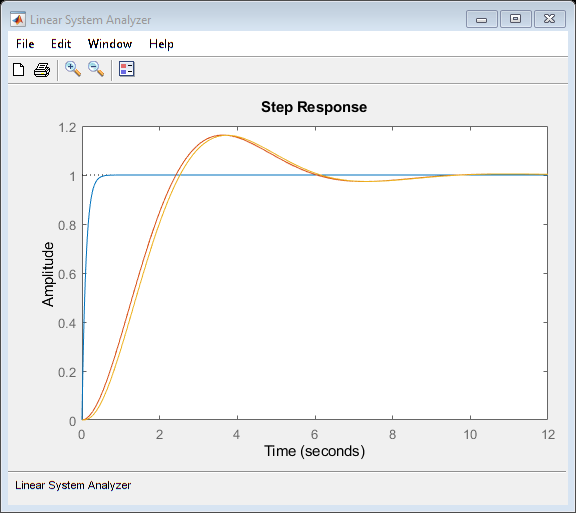

Wsoros=series(W1,W2);

%pzmap(W1,W2,Wsoros)
ltiview(W1,W2,Wsoros);

Parhuzamos

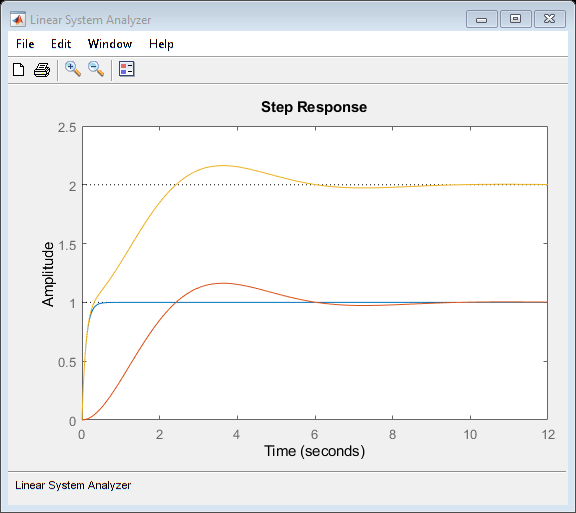

Wparhuzamos = parallel(W1,W2);

ltiview(W1,W2,Wparhuzamos);

Visszacsatolas / elore, visszacsat, kulonbseg kepzes

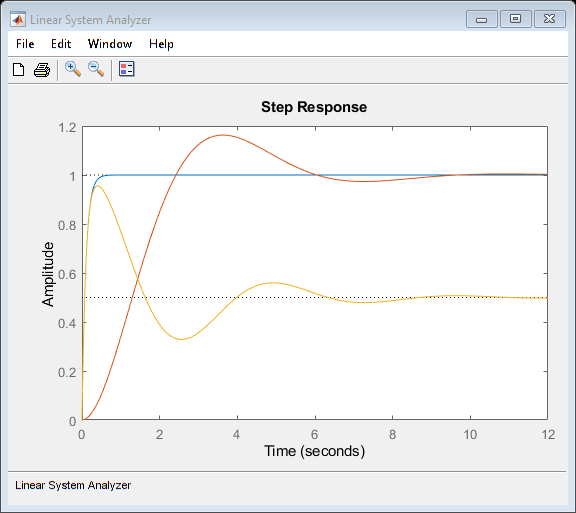

Wvissza=feedback(W1,W2,-1);

ltiview(W1,W2,Wvissza);

Mechanikus lengotag

k=0.5 , m = 2, b = 0.25

clear;clc;
m=2;k=0.5;b=0.25;
W=tf(1, [m b k])

W =
 
           1
  --------------------
  2 s^2 + 0.25 s + 0.5
 
Continuous-time transfer function.




dcgain(W)

ans = 2

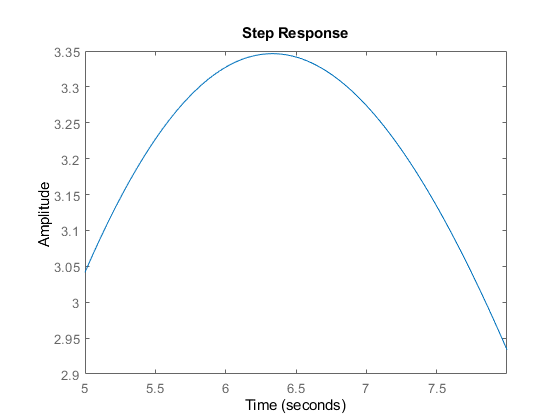

step(W,5:0.01:8);

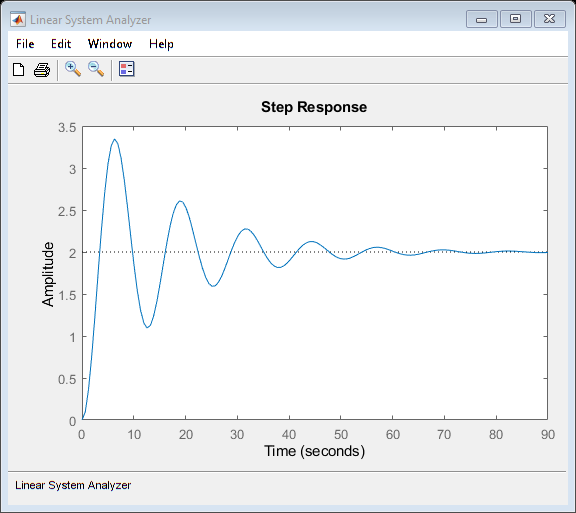


ltiview(W);

Atvitelek adottak, vizsgaljuk

clear;clc;
A=5; T1=10;T2=4;T3=1;
W= tf(A, conv([T1 1], conv([T2 1],[T3 1])))

W =
 
              5
  --------------------------
  40 s^3 + 54 s^2 + 15 s + 1
 
Continuous-time transfer function.



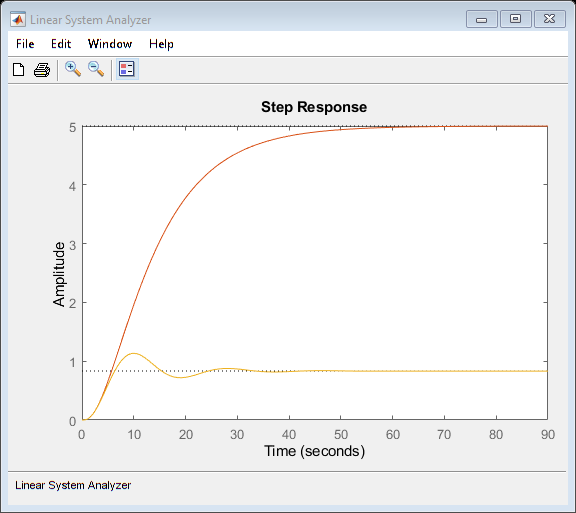

Wc1=tf(1,1);
W0=W*Wc1; %felnyitott kor
Wcl = feedback(W*Wc1, 1, -1); %zart kor
ltiview(W,W0,Wcl);


K=A;
hiba = 1/(1+K);
elteres_inputtol=1 - (1/(1+K))

elteres_inputtol = 0.8333

W_c -t megvaltoztatjuk 3-ra

A=5; T1=10;T2=4;T3=1;
W= tf(A, conv([T1 1], conv([T2 1],[T3 1])))

W =
 
              5
  --------------------------
  40 s^3 + 54 s^2 + 15 s + 1
 
Continuous-time transfer function.



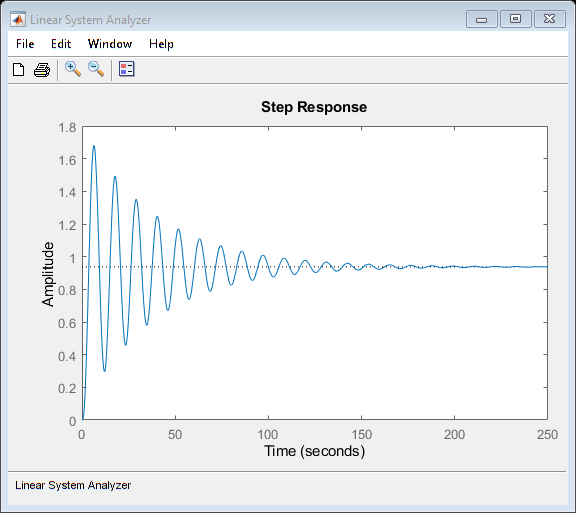

Wc2=tf(3,1);
W02=W*Wc2; %felnyitott kor
Wcl2 = feedback(W*Wc2, 1, -1); %zart kor
ltiview(Wcl2);

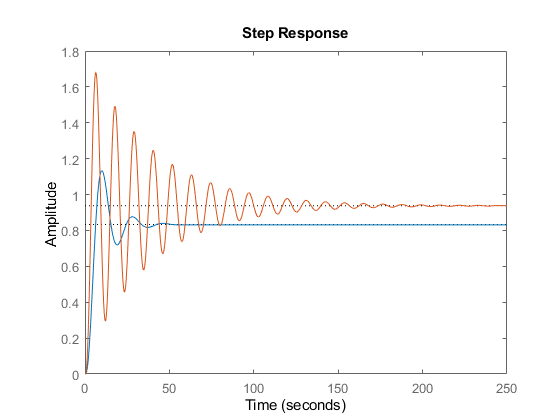

step(Wcl, Wcl2);


K=3*A;
hiba = 1/(1+K)

hiba = 0.0625

elteres_inputtol=1 - (1/(1+K))

elteres_inputtol = 0.9375

W_c -t 5-re valtoztatva instabil lesz.

Szabalyzo parameterei adottak, vizsgaljuk meg

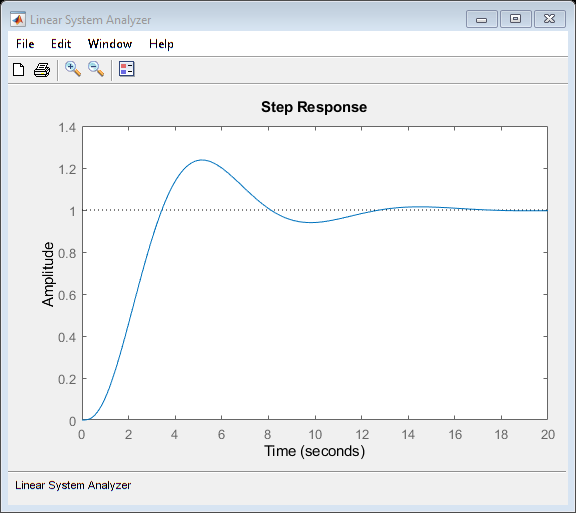

clc;clear;
A=5; T1=10;T2=4;T3=1;
Ap= 1.7666; Ti= 13.4756; Td=2.4439; Tc=0.5244;

W= tf(A, conv([T1 1], conv([T2 1],[T3 1])));

Wc= Ap*(tf(1,1)+tf(1, [Ti 0])+tf([Td 0],[Tc 1]));
W0_4 = W*Wc; Wcl4=feedback(W0_4,1,-1);
ltiview(Wcl4);